% Import excel spreadsheets as tables
optimalData1 = readtable("OptimalStep_0.4V_1.5V_clean.xlsx");
optimalData2 = readtable("OptimalStep_0.4V_2V_clean.xlsx");

magnetData1 = readtable("MagnetStep_0.45V_1.5V_clean.xlsx");
magnetData2 = readtable("MagnetStep_0.45V_2V_clean.xlsx");

heavyData2 = readtable("HeavyDiskTest_0.45V_1.5V_clean.xlsx");
heavyData1 = readtable("HeavyDiskTest_0.45V_1V_clean.xlsx");

% System ID toolbox results for 6 data sets
s = tf('s');

optimalTF1 = 3.862/(s+0.8121); 
optimalTF2 = 3.88/(s+0.8198); 

magnetTF1 = 5.443/(s+2.117); 
magnetTF2 = 6.382/(s+2.52); 

heavyTF1 = 0.621/(s+0.1358); 
heavyTF2 = 0.6915/(s+0.1453); 

% Optimal data measured and predicted results plots

% First Step Response, 0.4V - 1.5V

optimalTF1

optimalTF1 =
 
    3.862
  ----------
  s + 0.8121
 
Continuous-time transfer function.



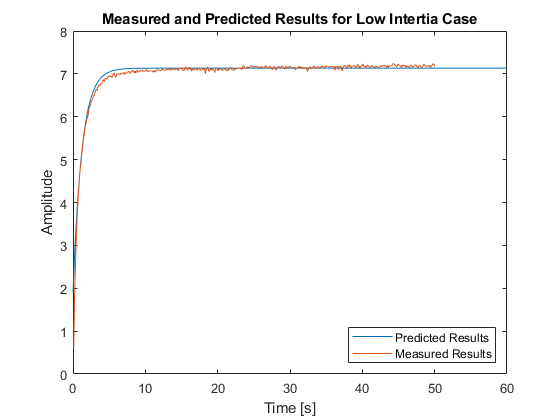

step1 = stepDataOptions('InputOffset', 0.4, 'StepAmplitude', 1.1); %Set input step
[optimalStep1, tOut] = step(optimalTF1, step1, 60); %store step data and time data in two variables

%plot of predicted results
plot(tOut, optimalStep1) 
hold on

%plot measured results from imported table
plot(optimalData1.time, optimalData1.velocity) 
hold off

title("Measured and Predicted Results for Low Intertia Case")
xlabel("Time [s]")
ylabel("Amplitude")
legend("Predicted Results", "Measured Results", 'Location','southeast','Orientation','vertical')


% Second Step Response, 0.4V - 2V

optimalTF2

optimalTF2 =
 
     3.88
  ----------
  s + 0.8198
 
Continuous-time transfer function.



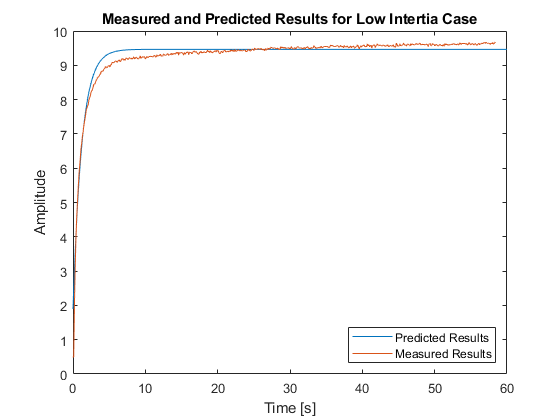

step2 = stepDataOptions('InputOffset', 0.4, 'StepAmplitude', 1.6); %Set input step
[optimalStep2, tOut] = step(optimalTF2, step2, 60); %store step data and time data in two variables

%plot of predicted results
plot(tOut, optimalStep2) 
hold on

%plot measured results from imported table
plot(optimalData2.time, optimalData2.velocity) 
hold off

title("Measured and Predicted Results for Low Intertia Case")
xlabel("Time [s]")
ylabel("Amplitude")
legend("Predicted Results", "Measured Results", 'Location','southeast','Orientation','vertical')

% Magnetic break data measured and predicted results plots

% First Step Response, 0.45V - 1.5V

magnetTF1

magnetTF1 =
 
    5.443
  ---------
  s + 2.117
 
Continuous-time transfer function.



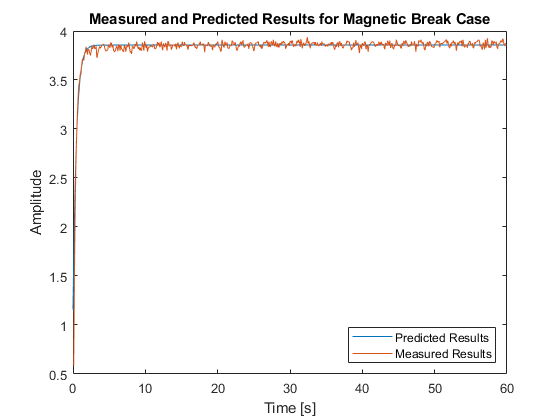

step1 = stepDataOptions('InputOffset', 0.45, 'StepAmplitude', 1.05); %Set input step
[magnetStep1, tOut] = step(magnetTF1, step1, 60); %store step data and time data in two variables

%plot of predicted results
plot(tOut, magnetStep1) 
hold on

%plot measured results from imported table
plot(magnetData1.time, magnetData1.velocity) 
hold off

title("Measured and Predicted Results for Magnetic Break Case")
xlabel("Time [s]")
ylabel("Amplitude")
legend("Predicted Results", "Measured Results", 'Location','southeast','Orientation','vertical')


% Second Step Response, 0.45V - 2V

magnetTF2

magnetTF2 =
 
   6.382
  --------
  s + 2.52
 
Continuous-time transfer function.



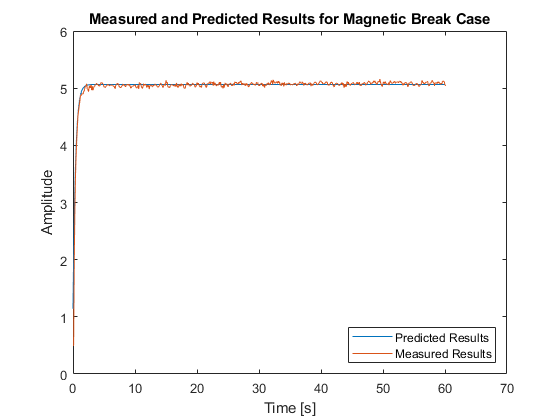

step2 = stepDataOptions('InputOffset', 0.45, 'StepAmplitude', 1.55); %Set input step
[magnetStep2, tOut] = step(magnetTF2, step2, 60); %store step data and time data in two variables

%plot of predicted results
plot(tOut, magnetStep2) 
hold on

%plot measured results from imported table
plot(magnetData2.time, magnetData2.velocity) 
hold off

title("Measured and Predicted Results for Magnetic Break Case")
xlabel("Time [s]")
ylabel("Amplitude")
legend("Predicted Results", "Measured Results", 'Location','southeast','Orientation','vertical')

% Magnetic break data measured and predicted results plots

% First Step Response, 0.45V - 1V

heavyTF1

heavyTF1 =
 
    0.621
  ----------
  s + 0.1358
 
Continuous-time transfer function.



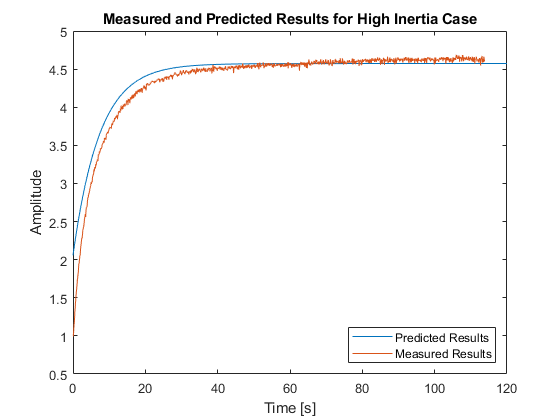

step1 = stepDataOptions('InputOffset', 0.45, 'StepAmplitude', 0.55); %Set input step
[heavyStep1, tOut] = step(heavyTF1, step1, 120); %store step data and time data in two variables

%plot of predicted results
plot(tOut, heavyStep1) 
hold on

%plot measured results from imported table
plot(heavyData1.time, heavyData1.velocity) 
hold off

title("Measured and Predicted Results for High Inertia Case")
xlabel("Time [s]")
ylabel("Amplitude")
legend("Predicted Results", "Measured Results", 'Location','southeast','Orientation','vertical')


% Second Step Response, 0.45V - 1.5V

heavyTF2

heavyTF2 =
 
    0.6915
  ----------
  s + 0.1453
 
Continuous-time transfer function.



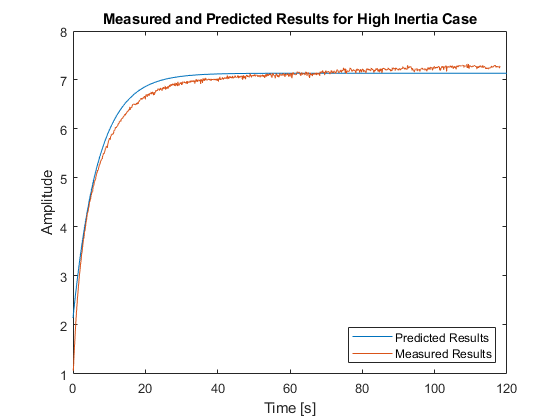

step2 = stepDataOptions('InputOffset', 0.45, 'StepAmplitude', 1.05); %Set input step
[heavyStep2, tOut] = step(heavyTF2, step2, 120); %store step data and time data in two variables

%plot of predicted results
plot(tOut, heavyStep2) 
hold on

%plot measured results from imported table
plot(heavyData2.time, heavyData2.velocity)
hold off

title("Measured and Predicted Results for High Inertia Case")
xlabel("Time [s]")
ylabel("Amplitude")
legend("Predicted Results", "Measured Results", 'Location','southeast','Orientation','vertical')